fname = '2021-05-09-19-20-26.bag';
% Create a bag file object with the file name by omitting the
% semicolon this displays some information about the bag file
bag = rosbag(fname);
  
% Display a list of the topics and message types in the bag file
bag.AvailableTopics;
 
%% Create a time series of the Odometry data
% Retrieve the messages as a cell array
odom_msgs = select(bag,'Topic','/cora/sensors/p3d');
 
% Create a timeseries object of the subset of message fields we are interested in
odom_ts = timeseries(odom_msgs,'Pose.Pose.Position.X','Pose.Pose.Position.Y', ...
    'Pose.Pose.Orientation.W','Pose.Pose.Orientation.X','Pose.Pose.Orientation.Y','Pose.Pose.Orientation.Z', ...
    'Twist.Twist.Linear.X','Twist.Twist.Angular.Z');

%% Create a time series of the command data
% Retrieve the messages as a cell array
cmd_msgs = select(bag,'Topic','/cora/cmd_vel');
 
% Create a timeseries object of the subset of message fields we are interested in
cmd_ts = timeseries(cmd_msgs,'Linear.X','Angular.Z');

%% Plot Surge Velocity and Setpoint/Goal
figure(1); clf();
% Plot the Data index corresponding to Twist.Twist.Linear.X
plot(odom_ts.Time,odom_ts.Data(:,7))

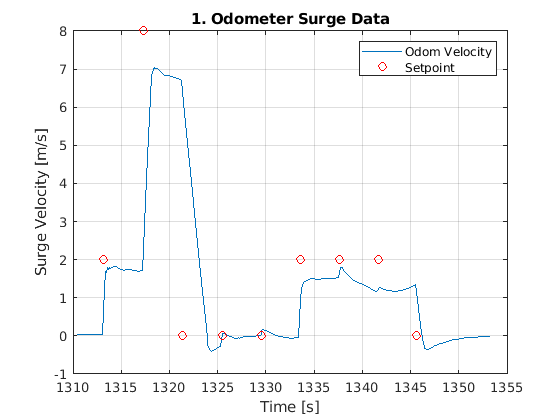

hold on
% Plot the Data index corresponding to Linear.X
plot(cmd_ts.Time, cmd_ts.Data(:,1),'ro')
xlabel('Time [s]')
ylabel('Surge Velocity [m/s]')
legend('Odom Velocity','Setpoint')
grid on
title('1. Odometer Surge Data')

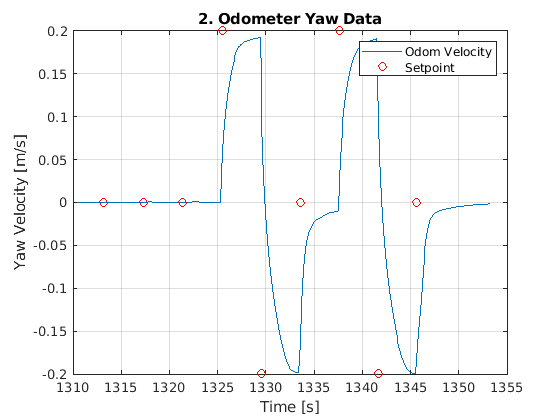


%% Plot Yaw Velocity and Setpoint/Goal
figure(2); clf();
% Plot the Data index corresponding to Twist.Twist.Linear.X
plot(odom_ts.Time,odom_ts.Data(:,8))
hold on
% Plot the Data index corresponding to Linear.X
plot(cmd_ts.Time, cmd_ts.Data(:,2),'ro')
xlabel('Time [s]')
ylabel('Yaw Velocity [m/s]')
legend('Odom Velocity','Setpoint')
grid on
title('2. Odometer Yaw Data')

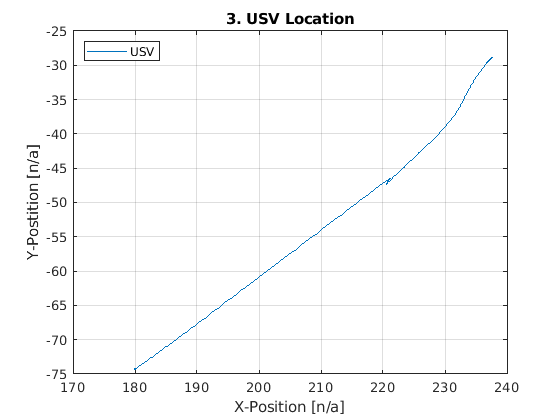


%% Plot X/Y Positions
figure(3); clf();
% Plot the Data index
plot(odom_ts.Data(:,1),odom_ts.Data(:,2))
xlabel('X-Position [n/a]')
ylabel('Y-Postition [n/a]')
legend('USV','Location','northwest')
grid on
title('3. USV Location')

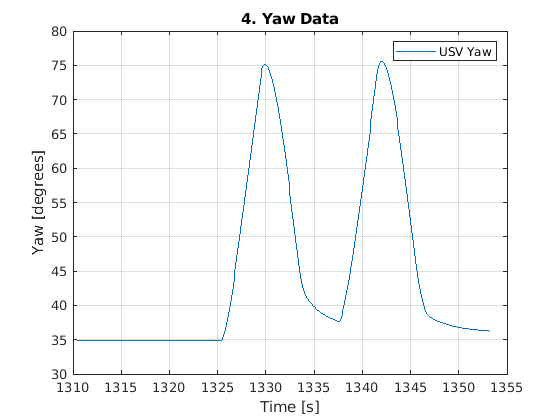


% Convert quaternion to Euler angle
% Note the convention for the quat2eul function is quaternion in order of WXYZ
q = odom_ts.Data(:,3:6);
e = quat2eul(q);
yaw = e(:,1);

%% Plot Yaw Displacement
figure(4); clf();
% Plot the Data index
plot(odom_ts.Time,rad2deg(yaw))
xlabel('Time [s]')
ylabel('Yaw [degrees]')
legend('USV Yaw')
grid on
title('4. Yaw Data')

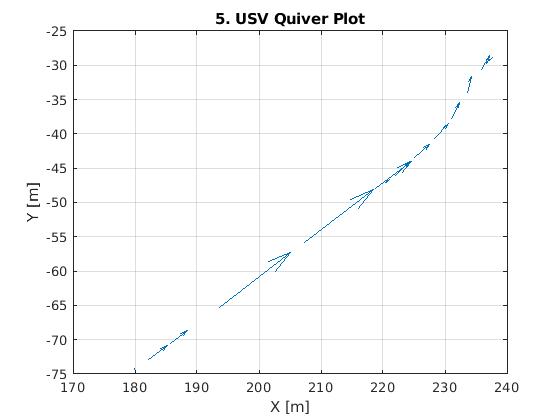


% Quiver Plot
% x is the x position of the USV
% y is the y position of the USV
% vel is the Linear.X velocity
% yaw is the heading angle of the USV in radians
 
x = odom_ts.Data(:,1);
y = odom_ts.Data(:,2);
u = odom_ts.Data(:,7).*cos(yaw);
v = odom_ts.Data(:,7).*sin(yaw);
 
figure(5); clf();
ii = 1:20:length(x);  % Decimate the data so that it plot only every Nth point.
quiver(x(ii),y(ii),u(ii),v(ii))
grid('on')
xlabel('X [m]')
ylabel('Y [m]')
title('5. USV Quiver Plot')

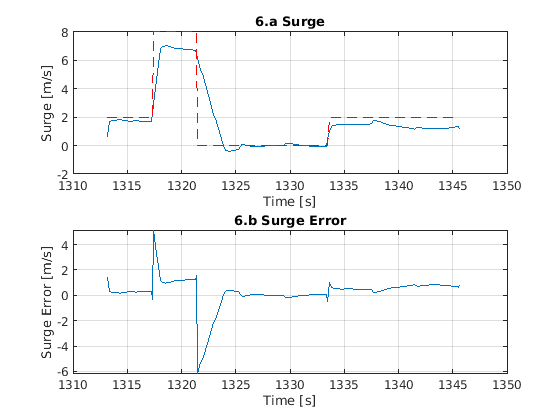


common_ts = interp1(cmd_ts.Time,cmd_ts.Data(:,1),odom_ts.Time,'previous');
% fix NaN
valid = ~isnan(common_ts);

% create error matrix
error = common_ts(valid) - odom_ts.Data(valid,7);

clf()
subplot(2,1,1)
plot(odom_ts.Time(valid),odom_ts.Data(valid,7))
hold on
plot(odom_ts.Time(valid),common_ts(valid),'r--')
grid on
title('6.a Surge')
xlabel('Time [s]')
ylabel('Surge [m/s]')

subplot(2,1,2)
plot(odom_ts.Time(valid),error)
grid on
title('6.b Surge Error')
xlabel('Time [s]')
ylabel('Surge Error [m/s]')

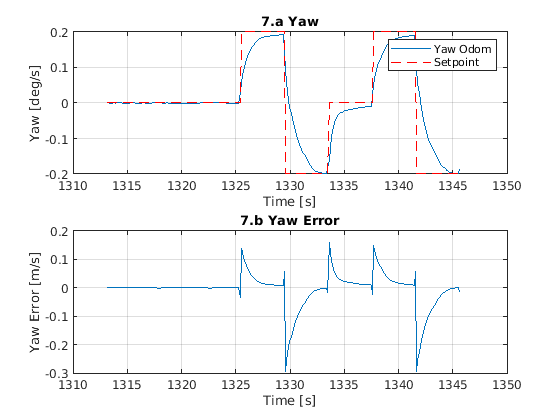


common_ts = interp1(cmd_ts.Time,cmd_ts.Data(:,2),odom_ts.Time,'previous');
% fix NaN
valid = ~isnan(common_ts);

% create error matrix
error = common_ts(valid) - odom_ts.Data(valid,8);

clf()
subplot(2,1,1)
plot(odom_ts.Time(valid),odom_ts.Data(valid,8))
hold on
plot(odom_ts.Time(valid),common_ts(valid),'r--')
grid on
title('7.a Yaw')
xlabel('Time [s]')
ylabel('Yaw [deg/s]')
legend('Yaw Odom','Setpoint')

subplot(2,1,2)
plot(odom_ts.Time(valid),error)
grid on
title('7.b Yaw Error')
xlabel('Time [s]')
ylabel('Yaw Error [m/s]')